% This MATLAB script trains and evaluates multiple machine learning models 
% (Decision Tree, SVM, k-NN, Random Forest, and Neural Network) using radar data.

% It loads preprocessed train, validation, and test sets, then:

% 1. Trains each model using the training set.

% 2. Evaluates each model on the validation set and selects the best model 
% based on validation accuracy.

% 3. Evaluates the best model on the test set.

% 4. Displays the validation and test accuracies and plots a confusion matrix 
% for the test set.

% Load the train, validation, and test data
load('train_data_flat.mat', 'XTrain', 'YTrain');
load('val_data_flat.mat', 'XVal', 'YVal');
load('test_data_flat.mat', 'XTest', 'YTest');

% Convert categorical labels to numeric values if needed
YTrain_num = double(YTrain);  % Convert categorical to numeric
YVal_num = double(YVal);
YTest_num = double(YTest);

% Initialize a struct to store model accuracies
model_accuracies = struct();

% 1. Decision Tree
fprintf('\nTraining Decision Tree...\n');


Training Decision Tree...


decisionTreeModel = fitctree(XTrain, YTrain_num);
YVal_pred = predict(decisionTreeModel, XVal);
val_accuracy = sum(YVal_pred == YVal_num) / numel(YVal_num);
fprintf('Validation Accuracy (Decision Tree): %.2f%%\n', val_accuracy * 100);

Validation Accuracy (Decision Tree): 12.50%


model_accuracies.DecisionTree = val_accuracy;

% 2. SVM (using ECOC for multi-class classification)
fprintf('\nTraining SVM (ECOC for multi-class classification)...\n');


Training SVM (ECOC for multi-class classification)...


svmModel = fitcecoc(XTrain, YTrain_num);  % Use fitcecoc for multi-class SVM

% Evaluate on validation set
YVal_pred = predict(svmModel, XVal);

% Calculate validation accuracy
val_accuracy = sum(YVal_pred == YVal_num) / numel(YVal_num);
fprintf('Validation Accuracy (SVM): %.2f%%\n', val_accuracy * 100);

Validation Accuracy (SVM): 12.50%


model_accuracies.SVM = val_accuracy;

% 3. k-NN (k = 5)
fprintf('\nTraining k-NN...\n');


Training k-NN...


knnModel = fitcknn(XTrain, YTrain_num, 'NumNeighbors', 5);
YVal_pred = predict(knnModel, XVal);
val_accuracy = sum(YVal_pred == YVal_num) / numel(YVal_num);
fprintf('Validation Accuracy (k-NN): %.2f%%\n', val_accuracy * 100);

Validation Accuracy (k-NN): 0.00%


model_accuracies.KNN = val_accuracy;

% 4. Random Forest (Ensemble of Decision Trees)
fprintf('\nTraining Random Forest...\n');


Training Random Forest...


rfModel = fitcensemble(XTrain, YTrain_num, 'Method', 'Bag');
YVal_pred = predict(rfModel, XVal);
val_accuracy = sum(YVal_pred == YVal_num) / numel(YVal_num);
fprintf('Validation Accuracy (Random Forest): %.2f%%\n', val_accuracy * 100);

Validation Accuracy (Random Forest): 0.00%


model_accuracies.RandomForest = val_accuracy;

% 5. Neural Network (Multilayer Perceptron)
fprintf('\nTraining Neural Network...\n');


Training Neural Network...


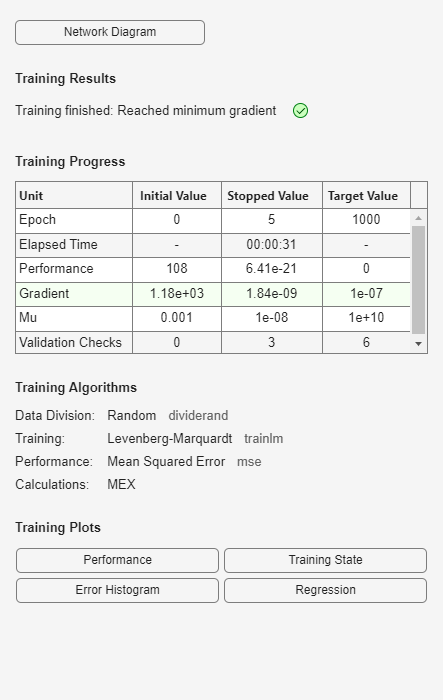

hiddenLayerSize = 10;  % Number of neurons in hidden layer
net = feedforwardnet(hiddenLayerSize);
net = train(net, XTrain', YTrain_num');

YVal_pred = net(XVal');
YVal_pred = round(YVal_pred);  % Round to nearest integer to classify
val_accuracy = sum(YVal_pred' == YVal_num) / numel(YVal_num);
fprintf('Validation Accuracy (Neural Network): %.2f%%\n', val_accuracy * 100);

Validation Accuracy (Neural Network): 0.00%


model_accuracies.NeuralNetwork = val_accuracy;

% Compare the validation accuracies for all models
fprintf('\nValidation Accuracies:\n');


Validation Accuracies:


disp(model_accuracies);

     DecisionTree: 0.1250
              SVM: 0.1250
              KNN: 0
     RandomForest: 0
    NeuralNetwork: 0




% Extract validation accuracies from the model_accuracies struct
accuracies = [model_accuracies.DecisionTree, model_accuracies.SVM, ...
              model_accuracies.KNN, model_accuracies.RandomForest, ...
              model_accuracies.NeuralNetwork];

% Find the index of the best model
[~, bestModelIdx] = max(accuracies);

% Model names
modelNames = {'DecisionTree', 'SVM', 'KNN', 'RandomForest', 'NeuralNetwork'};
bestModelName = modelNames{bestModelIdx};

fprintf('Best model: %s\n', bestModelName);

Best model: DecisionTree



% Final evaluation on the test set with the best model
fprintf('\nEvaluating the best model on the test set...\n');


Evaluating the best model on the test set...



switch bestModelName
    case 'DecisionTree'
        YTest_pred = predict(decisionTreeModel, XTest);
    case 'SVM'
        YTest_pred = predict(svmModel, XTest);
    case 'KNN'
        YTest_pred = predict(knnModel, XTest);
    case 'RandomForest'
        YTest_pred = predict(rfModel, XTest);
    case 'NeuralNetwork'
        YTest_pred = net(XTest');
        YTest_pred = round(YTest_pred);  % Round to classify
        YTest_pred = YTest_pred';
end

% Calculate test accuracy
test_accuracy = sum(YTest_pred == YTest_num) / numel(YTest_num);
fprintf('Test Accuracy (%s): %.2f%%\n', bestModelName, test_accuracy * 100);

Test Accuracy (DecisionTree): 0.00%


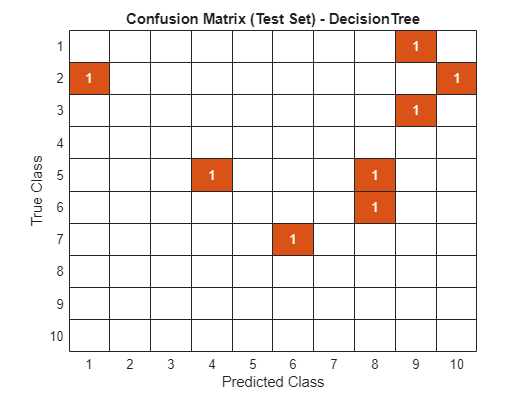


% Plot confusion matrix for the test set
figure;
confusionchart(YTest_num, YTest_pred);
title(sprintf('Confusion Matrix (Test Set) - %s', bestModelName));